R = 255;
G = 255;
B = 255;

T = [0.299, 0.587, 0.114;
     -0.168736, -0.331264, 0.5;
     0.5, -0.418688, -0.081312];

% Konwersja na liczbach double
Y_double = T(1, 1) * R + T(1, 2) * G + T(1, 3) * B;
Cb_double = T(2, 1) * R + T(2, 2) * G + T(2, 3) * B + 128;
Cr_double = T(3, 1) * R + T(3, 2) * G + T(3, 3) * B + 128;

disp("Wynik konwersji RGB->YCbCr na liczbach double:")

Wynik konwersji RGB->YCbCr na liczbach double:


disp(['Y: ', num2str(Y_double)])

Y: 255


disp(['Cb: ', num2str(Cb_double)])

Cb: 128


disp(['Cr: ', num2str(Cr_double)])

Cr: 128


% Ustal precyzję dla wartości RGB (8 bitów na część całkowitą, 0 na ułamkową)
prec_i_rgb = 8;
prec_f_rgb = 0;
word_rgb = 1 + prec_i_rgb + prec_f_rgb;

R_fix = fi(R, 1, word_rgb, prec_f_rgb);
G_fix = fi(G, 1, word_rgb, prec_f_rgb);
B_fix = fi(B, 1, word_rgb, prec_f_rgb);

% Ustal precyzję współczynników macierzy (18 bitów na część ułamkową)
prec_i_coeff = 1;
prec_f_coeff = 18;
word_coeff = prec_i_coeff + prec_f_coeff;

T_fix = T;
for i = 1:3
    for j = 1:3
        T_fix(i, j) = fi(T(i, j), 1, word_coeff, prec_f_coeff);
    end
end

% Obliczanie wartości Y, Cb, Cr na liczbach stałoprzecinkowych
Y_fix = T_fix(1, 1) * R_fix + T_fix(1, 2) * G_fix + T_fix(1, 3) * B_fix;
Cb_fix = T_fix(2, 1) * R_fix + T_fix(2, 2) * G_fix + T_fix(2, 3) * B_fix;
Cr_fix = T_fix(3, 1) * R_fix + T_fix(3, 2) * G_fix + T_fix(3, 3) * B_fix;

% Kwantyzacja wyników po mnożeniu (precyzja 9 bitów, 8 bitów na część całkowitą, 0 bitów na ułamkową)
prec_i_result = 8;
prec_f_result = 0;
word_result = 1 + prec_i_result + prec_f_result;

ntBP = numerictype(1, word_result, prec_f_result);

Y_quant = quantize(Y_fix, ntBP);
Cb_quant = quantize(Cb_fix, ntBP) + 128;
Cr_quant = quantize(Cr_fix, ntBP) + 128;

disp("Wyniki konwersji RGB->YCbCr na liczbach stałoprzecinkowych:")

Wyniki konwersji RGB->YCbCr na liczbach stałoprzecinkowych:


disp(['Y: ', num2str(double(Y_quant))])

Y: 254


disp(['Cb: ', num2str(double(Cb_quant))])

Cb: 127


disp(['Cr: ', num2str(double(Cr_quant))])

Cr: 128


% Ustal precyzję dla wartości RGB (8 bitów na część całkowitą, 0 na ułamkową)
prec_i_rgb = 8;
prec_f_rgb = 0;
word_rgb = 1 + prec_i_rgb + prec_f_rgb;

% Ustal precyzję współczynników macierzy (18 bitów na część ułamkową)
prec_i_coeff = 1;
prec_f_coeff = 18;
word_coeff = prec_i_coeff + prec_f_coeff;

% Kwantyzacja wyników po mnożeniu (precyzja 9 bitów, 8 bitów na część całkowitą, 0 bitów na ułamkową)
prec_i_result = 8;
prec_f_result = 0;
word_result = 1 + prec_i_result + prec_f_result;

ntBP = numerictype(1, word_result, prec_f_result);

% Wczytaj obraz PPM
image = imread('hand_photo.ppm');
[rows, cols, ~] = size(image);

% Przetwórz obraz piksel po pikselu
Y_image = zeros(rows, cols);
Cb_image = zeros(rows, cols);
Cr_image = zeros(rows, cols);

T = [0.299, 0.587, 0.114; 
    -0.168736, -0.331264, 0.5; 
     0.5, -0.418688, -0.081312];

% Przekształć macierz współczynników na stałoprzecinkową
T_fix = fi(T, 1, word_coeff, prec_f_coeff);

for i = 1:rows
    for j = 1:cols
        R = image(i, j, 1);
        G = image(i, j, 2);
        B = image(i, j, 3);
        
        R_fix = fi(R, 1, word_rgb, prec_f_rgb);
        G_fix = fi(G, 1, word_rgb, prec_f_rgb);
        B_fix = fi(B, 1, word_rgb, prec_f_rgb);
        
        % Obliczanie wartości Y, Cb, Cr na liczbach stałoprzecinkowych
        Y_fix = T_fix(1, 1) * R_fix + T_fix(1, 2) * G_fix + T_fix(1, 3) * B_fix;
        Cb_fix = T_fix(2, 1) * R_fix + T_fix(2, 2) * G_fix + T_fix(2, 3) * B_fix;
        Cr_fix = T_fix(3, 1) * R_fix + T_fix(3, 2) * G_fix + T_fix(3, 3) * B_fix;
        
        % Kwantyzacja wyników
        Y_quant = quantize(Y_fix, ntBP);
        Cb_quant = quantize(Cb_fix, ntBP) + 128;
        Cr_quant = quantize(Cr_fix, ntBP) + 128;
        
        % Zapisanie wyników do macierzy
        Y_image(i, j) = double(Y_quant);
        Cb_image(i, j) = double(Cb_quant);
        Cr_image(i, j) = double(Cr_quant);
    end
end

% Przekształcenie z powrotem z YCbCr na RGB
Y_image = uint8(Y_image);
Cb_image = uint8(Cb_image - 128);
Cr_image = uint8(Cr_image - 128);

R_image = Y_image + 1.402 * Cr_image;
G_image = Y_image - 0.344136 * Cb_image - 0.714136 * Cr_image;
B_image = Y_image + 1.772 * Cb_image;

% Połącz składowe RGB w jeden obraz
RGB_image = cat(3, R_image, G_image, B_image);

% Zapisywanie wyników do jednego pliku PPM
imwrite(RGB_image, 'YCbCr_to_RGB_image.ppm');

% Wczytaj wyniki symulacji z pliku 'out_00.ppm'
simulated_image = imread('out_00.ppm');

% Porównaj wyniki
diff_image = imabsdiff(RGB_image, simulated_image);

% % Wyświetl różnice
% imshow(diff_image);
% title('Różnice w obrazach RGB');

% Ustal precyzję dla wartości RGB (8 bitów na część całkowitą, 0 na ułamkową)
prec_i_rgb = 8;
prec_f_rgb = 0;
word_rgb = 1 + prec_i_rgb + prec_f_rgb;

% Ustal precyzję współczynników macierzy (18 bitów na część ułamkową)
prec_i_coeff = 1;
prec_f_coeff = 18;
word_coeff = prec_i_coeff + prec_f_coeff;

% Kwantyzacja wyników po mnożeniu (precyzja 9 bitów, 8 bitów na część całkowitą, 0 bitów na ułamkową)
prec_i_result = 8;
prec_f_result = 0;
word_result = 1 + prec_i_result + prec_f_result;

ntBP = numerictype(1, word_result, prec_f_result);

% Wczytaj obraz PPM
image = imread('hand_photo.ppm');
[rows, cols, ~] = size(image);

% Przetwórz obraz piksel po pikselu
Y_image = zeros(rows, cols);
Cb_image = zeros(rows, cols);
Cr_image = zeros(rows, cols);

T = [0.299, 0.587, 0.114; 
    -0.168736, -0.331264, 0.5; 
     0.5, -0.418688, -0.081312];

% Przekształć macierz współczynników na stałoprzecinkową
T_fix = fi(T, 1, word_coeff, prec_f_coeff);

for i = 1:rows
    for j = 1:cols
        R = image(i, j, 1);
        G = image(i, j, 2);
        B = image(i, j, 3);
        
        R_fix = fi(R, 1, word_rgb, prec_f_rgb);
        G_fix = fi(G, 1, word_rgb, prec_f_rgb);
        B_fix = fi(B, 1, word_rgb, prec_f_rgb);
        
        % Obliczanie wartości Y, Cb, Cr na liczbach stałoprzecinkowych
        Y_fix = T_fix(1, 1) * R_fix + T_fix(1, 2) * G_fix + T_fix(1, 3) * B_fix;
        Cb_fix = T_fix(2, 1) * R_fix + T_fix(2, 2) * G_fix + T_fix(2, 3) * B_fix;
        Cr_fix = T_fix(3, 1) * R_fix + T_fix(3, 2) * G_fix + T_fix(3, 3) * B_fix;
        
        % Kwantyzacja wyników
        Y_quant = quantize(Y_fix, ntBP);
        Cb_quant = quantize(Cb_fix, ntBP) + 128;
        Cr_quant = quantize(Cr_fix, ntBP) + 128;
        
        % Zapisanie wyników do macierzy
        Y_image(i, j) = double(Y_quant);
        Cb_image(i, j) = double(Cb_quant);
        Cr_image(i, j) = double(Cr_quant);
    end
end

% Połącz składowe YCbCr w jeden obraz
YCbCr_image = cat(3, uint8(Y_image), uint8(Cb_image), uint8(Cr_image));

% Zapisywanie wyników do jednego pliku PPM
fileID = fopen('YCbCr_image.ppm', 'w');
fprintf(fileID, 'P6\n');
fprintf(fileID, '%d %d\n', cols, rows);
fprintf(fileID, '255\n');
fwrite(fileID, permute(YCbCr_image, [2 1 3]), 'uint8');
fclose(fileID);

% Wczytaj wyniki symulacji z pliku 'out_00.ppm'
simulated_image = imread('out_00.ppm');
disp("obrazek z vivado")

obrazek z vivado


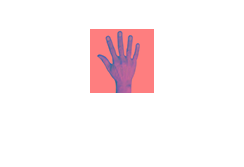

imshow(simulated_image);

disp("obrazek matlabowy")

obrazek matlabowy


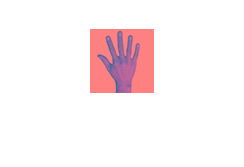

imshow(YCbCr_image);

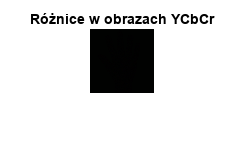


% Porównaj wyniki
diff_image = imabsdiff(YCbCr_image, simulated_image);

% Wyświetl różnice
imshow(diff_image);
title('Różnice w obrazach YCbCr');

porownanie = abs(YCbCr_image-simulated_image)

porownanie = 64×64×3 uint8 array
porownanie(:,:,1) =

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   2   1   1   1   1   1   1   1   1   1   1   1   1   

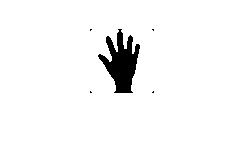

image = imread('hand_photo.ppm');
[rows, cols, ~] = size(image);
gray_image = rgb2gray(image);
binary_image = imbinarize(gray_image);
median_filtered_image = medfilt2(binary_image, [5 5]);
fileID = fopen('median_image.ppm', 'w');
fprintf(fileID, 'P5\n'); % Format P5 dla binarnego obrazu w skali szarości
fprintf(fileID, '%d %d\n', cols, rows);
fprintf(fileID, '255\n');
fwrite(fileID, median_filtered_image', 'uint8'); % Transponujemy obraz, aby zachować porządek wierszy
fclose(fileID);
imshow(median_filtered_image);